## Uniqueness & existence of LU - Ex. 5.1

clear all;
close all;
clc;

Consider the system $Ex = b$

E = [4 1 1 1 5;
    4 1 2 0 0;
    1 0 15 5 1;
    0 2 4 10 2;
    3 1 2 4 20]

E =      4     1     1     1     5
     4     1     2     0     0
     1     0    15     5     1
     0     2     4    10     2
     3     1     2     4    20



b = [12 19 22 18 30]'

b =     12
    19
    22
    18
    30


### a. Verify with MATLAB that the sufficient conditions for the existence and uniqueness of the LU decomposition without pivoting are not fullfilled by matrix E

Let's check if E is diagonally dominant by rows


$$|a_{ii}| > \sum_{j=1, i\neq j}^n |a_{ij}|, \forall i = 1,...,n$$


n = length(E);
ddr = true;

for i = 1:n
    s = sum(abs(E(i, :))) - abs(E(i,i));
    
    if abs(E(i,i)) <= s
        ddr = false;        
        break;
    end
end

if ddr
    fprintf("E DIAGONALLY DOMINANT by rows");
else
    fprintf("E NOT DIAGONALLY DOMINANT by rows");
end

E NOT DIAGONALLY DOMINANT by rows

Let's check if E is diagonally dominant by columns


$$|a_{ii}| > \sum_{j=1, i\neq j}^n |a_{ji}|, \forall i = 1,...,n$$


n = length(E);
ddr = true;

for i = 1:n
    s = sum(abs(E(:, i))) - abs(E(i,i));
    
    if abs(E(i,i)) <= s
        ddr = false;        
        break;
    end
end

if ddr
    fprintf("E DIAGONALLY DOMINANT by columns");
else
    fprintf("E NOT DIAGONALLY DOMINANT by columns");
end

E NOT DIAGONALLY DOMINANT by columns

Let's check if E is spd (symmetric positive defined)

E_T = E'

E_T =      4     4     1     0     3
     1     1     0     2     1
     1     2    15     4     2
     1     0     5    10     4
     5     0     1     2    20



if E_T == E
    fprintf("E is SYMMETRIC");
else
    fprintf("E is NOT SYMMETRIC");
end

E is NOT SYMMETRIC


eigenvalues_E = eig(E)

eigenvalues_E =    22.8002
    0.1618
    4.1823
    6.7672
   16.0885



if eigenvalues_E > 0
    fprintf("E is POSITIVE DEFINITE");
else
    fprintf("E is NOT POSITIVE DEFINITE");
end

E is POSITIVE DEFINITE

The matrix E is not symmetric, so the sufficient conditions for the existence & uniqueness are not fulfill.

### b. Compute the LU of matrix E with the Matlab command lu and verify if pivoting taking place with the Matlab command spy.

[L, U] = lu(E)

L =     1.0000         0         0         0         0
    1.0000         0    0.0656   -0.8173    1.0000
    0.2500   -0.1250    1.0000         0         0
         0    1.0000         0         0         0
    0.7500    0.1250    0.0492    1.0000         0


U =     4.0000    1.0000    1.0000    1.0000    5.0000
         0    2.0000    4.0000   10.0000    2.0000
         0         0   15.2500    6.0000         0
         0         0         0    1.7049   16.0000
         0         0         0         0    8.0769


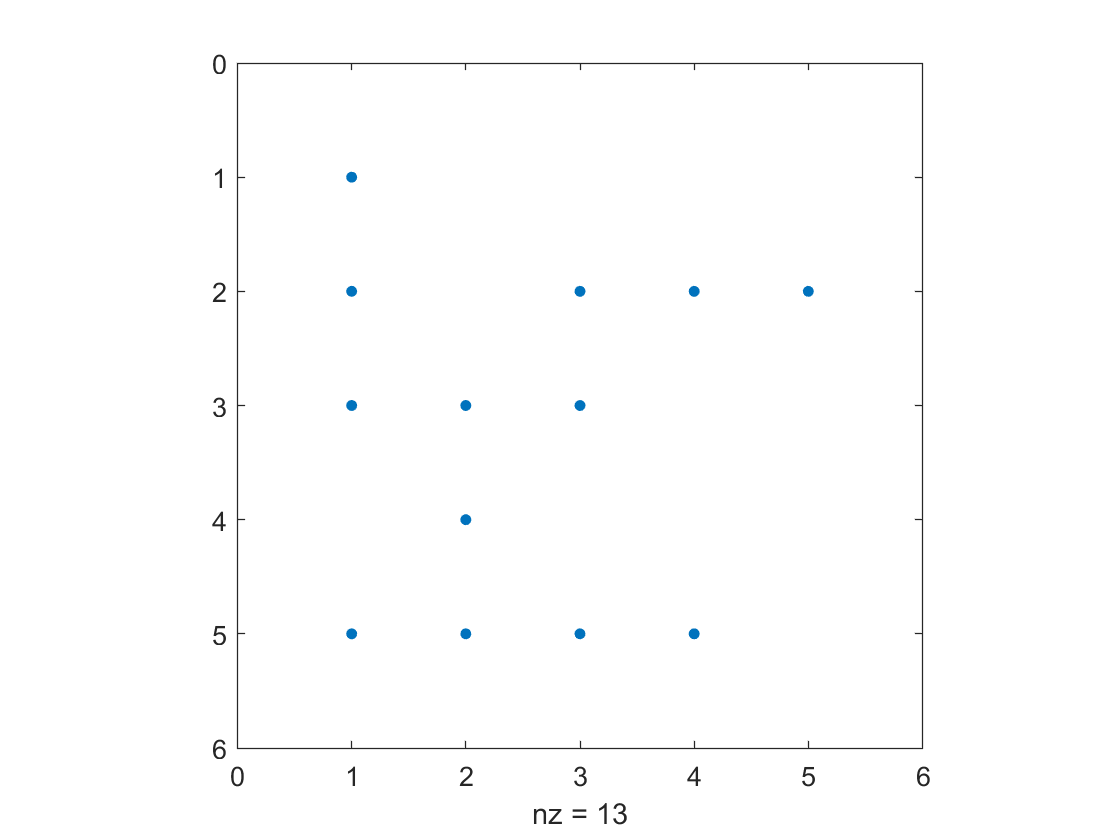


spy(L);

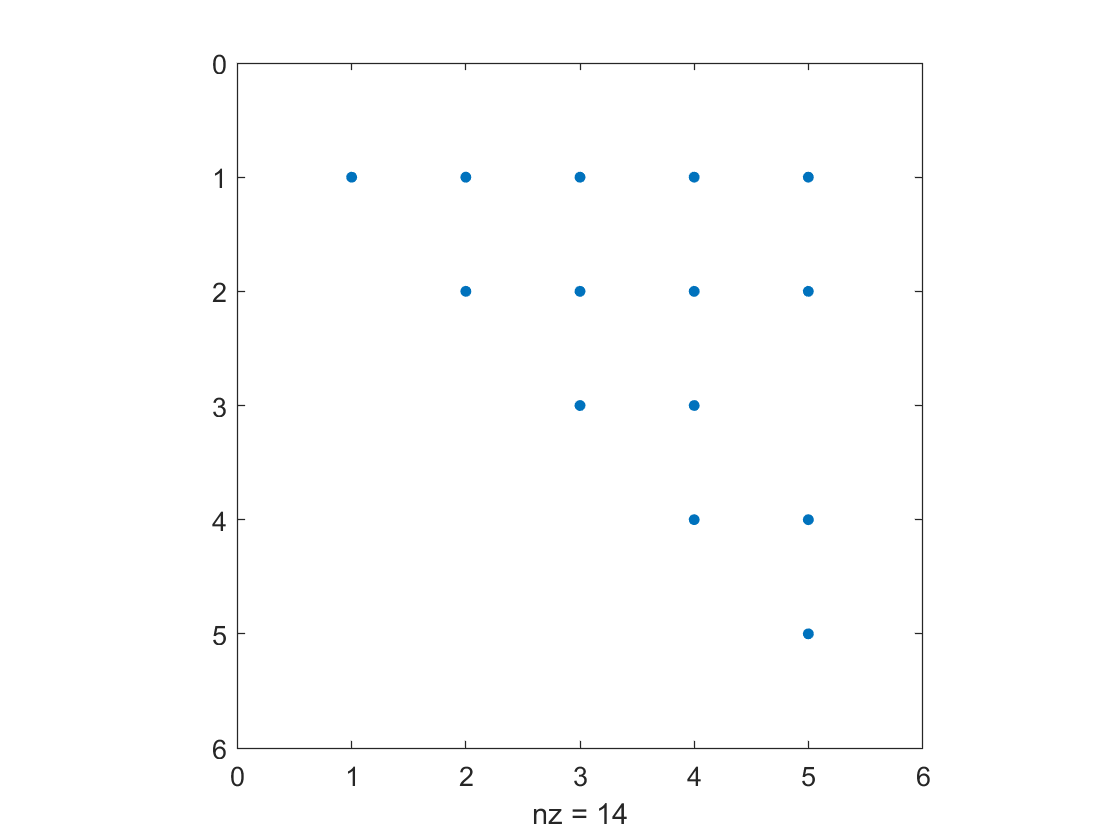

spy(U);

Pivoting happened due to the fact that L is not a lower triangolar matrix.

### c. Solve the system $Ex = b$ by using the LU decomposition at the previous item.

y = L \ b

y =    12.0000
   18.0000
   21.2500
   17.7049
   20.0769


x = U \ y

x =   -13.0571
   58.2571
    6.4857
  -12.9429
    2.4857


Let's check the solution

comp_b = round(E*x)

comp_b =     12
    19
    22
    18
    30


b

b =     12
    19
    22
    18
    30
